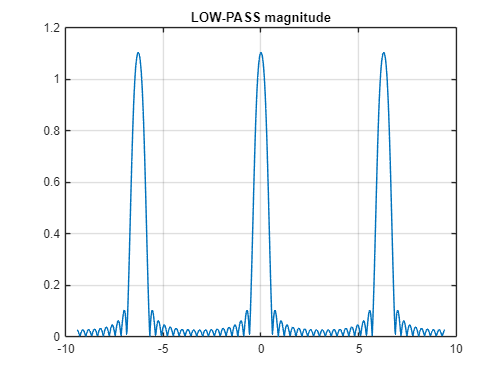

clear; clc; close all;
% Gigital Filter : low pass -> band pass
% Define Center Freq, Cutoff Freq, Bandwidth (rad/sample)
% Generate FIR hd[n] : (2/(pi*n) * sin(n*wc) * cos(n*w0);
wc    = pi/8;          
w0_HP = pi;           
w0_BP = 0.5*pi;        
w0_BR = pi/3;         

M  = 10;
L  = 2*M + 1;
n  = -M:M;

%% LOW-PASS
hLP = zeros(1,L);
for x = 1:L
    if n(x) == 0
        hLP(x) = wc/pi;
    else
        hLP(x) = sin(wc*n(x)) / (pi*n(x));
    end
end

%% HIGH-PASS
hHP = zeros(1,L);
for x = 1:L
    hHP(x) = hLP(x) * cos(w0_HP*n(x)); 
end

%% BAND-PASS
hBP = zeros(1,L);
for x = 1:L
    if n(x) == 0
        hBP(x) = (2*wc)/pi;
    else
        hBP(x) = (2/(pi*n(x))) * sin(wc*n(x)) * cos(w0_BP*n(x));
    end
end

%% BAND-REJECT
hBP_for_BR = zeros(1,L);
for x = 1:L
    if n(x) == 0
        hBP_for_BR(x) = (2*wc)/pi;
    else
        hBP_for_BR(x) = (2/(pi*n(x))) * sin(wc*n(x)) * cos(w0_BR*n(x));
    end
end

hBR = zeros(1,L);
for x = 1:L
    if n(x) == 0
        hBR(x) = 1 - hBP_for_BR(x);   
    else
        hBR(x) = -hBP_for_BR(x);      
    end
end

%% DTFT
w = linspace(-3*pi, 3*pi, 1001);

HLP = zeros(1,length(w));
HHP = zeros(1,length(w));
HBP = zeros(1,length(w));
HBR = zeros(1,length(w));

for x = 1:length(w)
    sLP = 0; sHP = 0; sBP = 0; sBR = 0;

    for y = 1:L
        ejw = exp(-1j*w(x)*n(y));
        sLP = sLP + hLP(y) * ejw;
        sHP = sHP + hHP(y) * ejw;
        sBP = sBP + hBP(y) * ejw;
        sBR = sBR + hBR(y) * ejw;
    end

    HLP(x) = sLP;
    HHP(x) = sHP;
    HBP(x) = sBP;
    HBR(x) = sBR;
end

figure(1);
plot(w, abs(HLP), 'LineWidth', 1.2); grid on;
title('LOW-PASS magnitude');

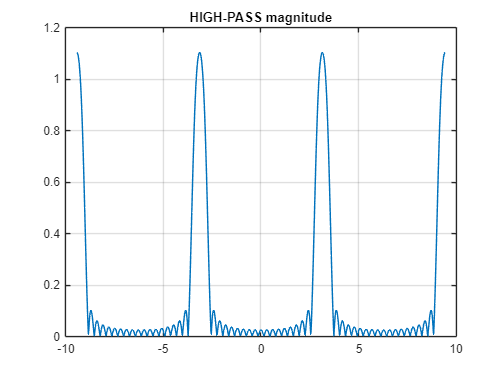


figure(2);
plot(w, abs(HHP), 'LineWidth', 1.2); grid on;
title('HIGH-PASS magnitude');

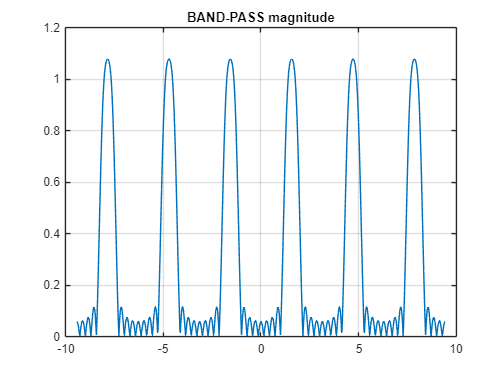


figure(3);
plot(w, abs(HBP), 'LineWidth', 1.2); grid on;
title('BAND-PASS magnitude');

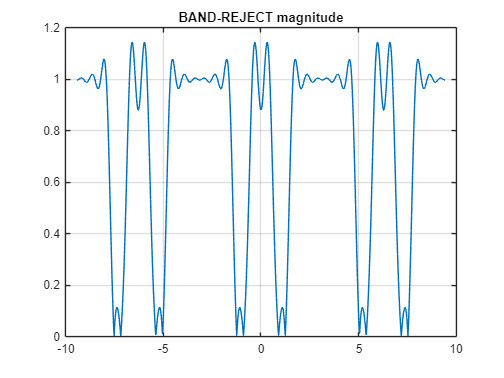


figure(4);
plot(w, abs(HBR), 'LineWidth', 1.2); grid on;
title('BAND-REJECT magnitude');